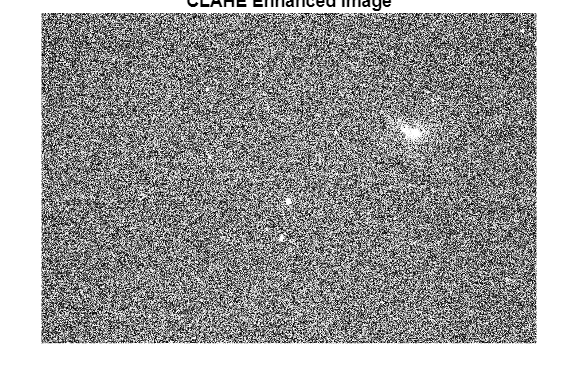

clc ; clear all ; close all ;
img = imread("D:\IMAGES\ORION\pipp_20240331_003120\_MG_0082\_MG_0047.tif"); % Replace with your image file

% Convert the image to grayscale if it is in RGB
if size(img, 3) == 3
    img_gray = rgb2gray(img);
else
    img_gray = img;
end

clahe_img = adapthisteq(img_gray, 'ClipLimit', 0.1, 'NumTiles', [2 2]);
clahe_img1 = adapthisteq(clahe_img, 'ClipLimit', 0.1, 'NumTiles', [2 2]);
imshow(clahe_img1);
title('CLAHE Enhanced Image');

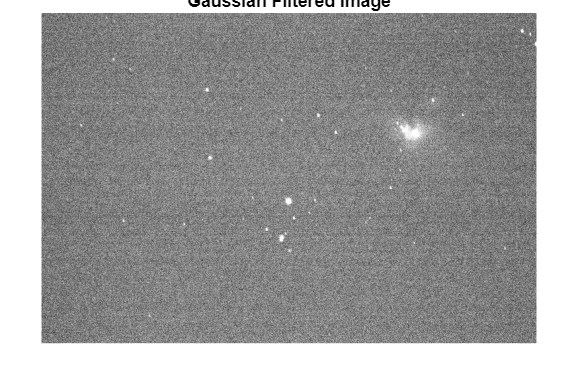

filteredImage = imgaussfilt(clahe_img1, 4); 
imshow(filteredImage);
title('Gaussian Filtered Image');

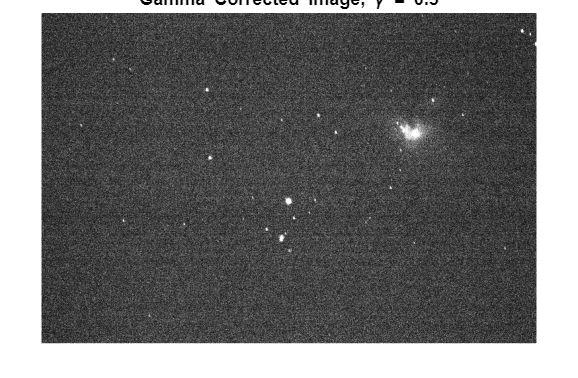

image_double = im2double(filteredImage);
gamma = 0.5;

% Apply gamma correction to each channel (R, G, B)
corrected_image = image_double .^ (1/gamma);

% Display the gamma-corrected image
figure;
imshow(corrected_image);
title(['Gamma Corrected Image, \gamma = ', num2str(gamma)]);

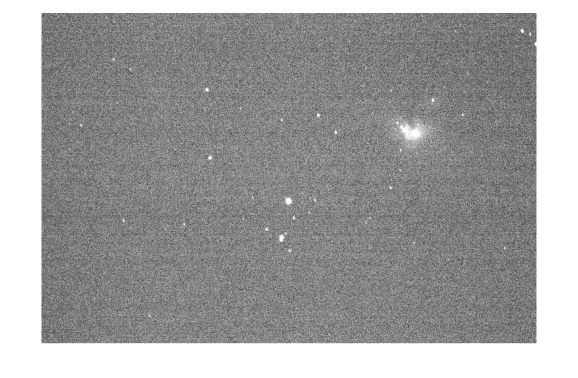

if size(corrected_image, 3) == 1
    img = cat(3, corrected_image, corrected_image, corrected_image);  % Replicate grayscale to RGB
end

% Adjust contrast using imadjust
contrast_img = imadjust(img, [0 0 0; 1 1 1], []);

% Apply gamma correction for better brightness adjustment
gamma_value = 0.5;  % You can experiment with different values
gamma_corrected_img = imadjust(contrast_img, [], [], gamma_value);

imshow(gamma_corrected_img);

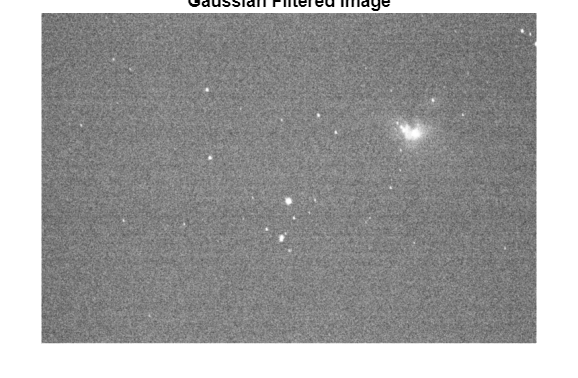

filtered1Image = imgaussfilt(gamma_corrected_img, 4); 
imshow(filtered1Image);
title('Gaussian Filtered Image');

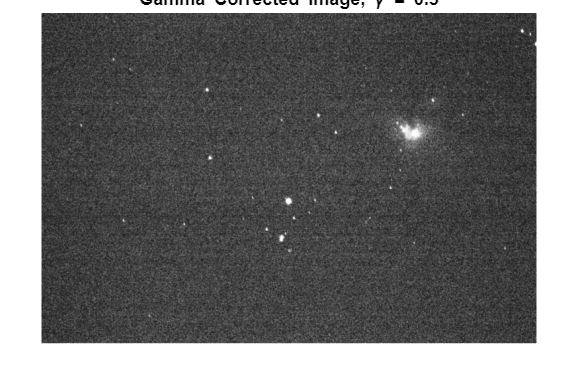

image_double = im2double(filtered1Image);
gamma = 0.5;

% Apply gamma correction to each channel (R, G, B)
corrected1_image = image_double .^ (1/gamma);

% Display the gamma-corrected image
figure;
imshow(corrected1_image);
title(['Gamma Corrected Image, \gamma = ', num2str(gamma)]);

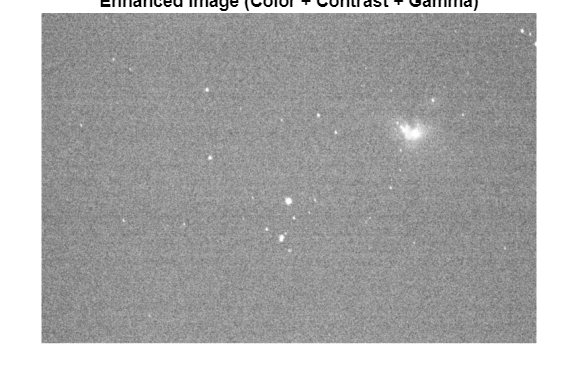

img = corrected1_image ;

% If the image is grayscale, convert it to RGB
if size(img, 3) == 1
    img = cat(3, img, img, img);  % Replicate grayscale to RGB
end

% Adjust contrast using imadjust for RGB
contrast_img = imadjust(img, [0 0 0; 1 1 1], []);  % Specify range for RGB

% Apply gamma correction for better brightness adjustment
gamma_value = 0.4;  % You can experiment with different values
gamma_corrected_img = imadjust(contrast_img, [], [], gamma_value);

imshow(gamma_corrected_img);
title('Enhanced Image (Color + Contrast + Gamma)');

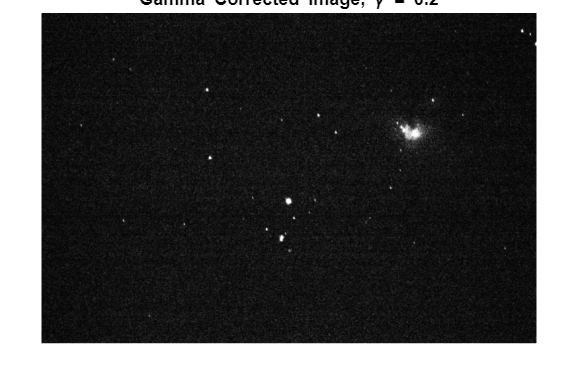

image_double = im2double(gamma_corrected_img);
gamma = 0.2;

% Apply gamma correction to each channel (R, G, B)
corrected1_image = image_double .^ (1/gamma);

% Display the gamma-corrected image
figure;
imshow(corrected1_image);
title(['Gamma Corrected Image, \gamma = ', num2str(gamma)]);

inputImage = corrected1_image ;

filterSize = 3;  % Define filter size (e.g., 3x3)
Q = 1.5;  % Choose the value of Q

outputImage = contraharmonicMeanFilter(inputImage, filterSize, Q);

imshow(outputImage), title('Contraharmonic Mean Filtered Image');

function output = contraharmonicMeanFilter(inputImage, filterSize, Q)
    % Convert image to double for calculations
    inputImage = double(inputImage);
    
    % Get the size of the input image
    [rows, cols] = size(inputImage);
    
    % Define the output image
    output = zeros(rows, cols);
    
    % Define the padding size
    padSize = floor(filterSize / 2);
    
    % Pad the input image to handle borders
    paddedImage = padarray(inputImage, [padSize padSize], 'symmetric');
    
    % Apply the contraharmonic mean filter
    for i = 1:rows
        for j = 1:cols
            % Extract the current neighborhood
            region = paddedImage(i:i+filterSize-1, j:j+filterSize-1);
            
            % Compute the contraharmonic mean
            numerator = sum(sum(region.^(Q+1)));
            denominator = sum(sum(region.^Q));
            
            % Avoid division by zero
            if denominator ~= 0
                output(i,j) = numerator / denominator;
            else
                output(i,j) = 0;
            end
        end
    end
    
    % Convert output back to uint8 (if original image is in uint8 format)
    output = uint8(output);
end
